# Ejercicio 1

Este ejercicio es una toma de contacto con las funciones para la generación de redes neruonales competitivas.

Primeros generamos los clusters y los puntos.

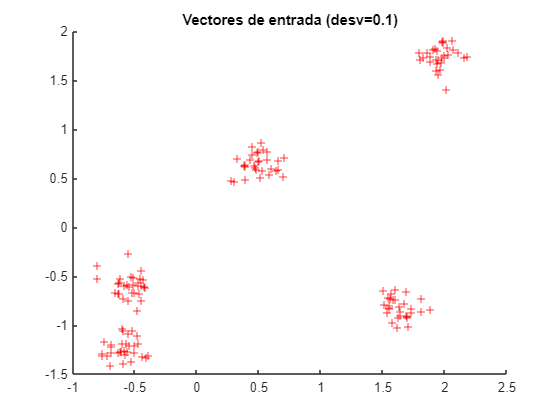

% Close old figures
close all;

% Definition of function parameters for cluster generation
n_clusters = 5; %TODO: Change from 4 to 8
desv = 0.1; %TODO: Change from 0.1 to 0.4
n_points = 30;
limits = [-2 2; -2 2];
X = generar_grupos(limits, n_clusters, n_points, desv); % X is [2xN]; N=n_clusters*n_points

% Plot clusters
figure(); hold on;
title(sprintf('Vectores de entrada (desv=%0.1f)', desv));
plot(X(1,:), X(2,:), '+r')

Implementation of the Competitive Neural Network with `competlayer` function.

num_unidades = n_clusters; % Same neurons as clusters
red = competlayer(num_unidades);

Entrenamiento de la red neuronal.

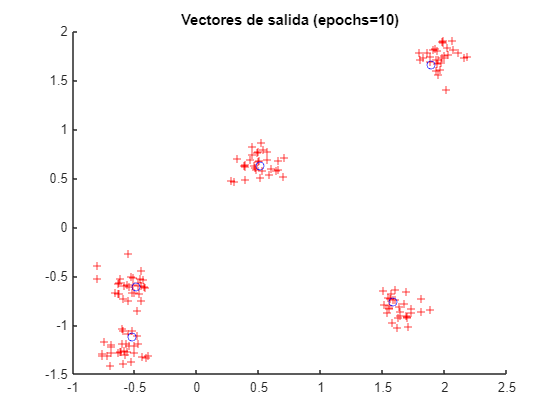

% Definition of the number of epochs
red.trainParam.epochs=10;

% Training
red = train(red, X);

% Weights matrix
W = red.IW{1}; % W is [n_clusters x 2]

% Plot the centroid od each cluster
title(sprintf('Vectores de salida (epochs=%d)', red.trainParam.epochs));
plot(W(:,1), W(:,2), 'ob');